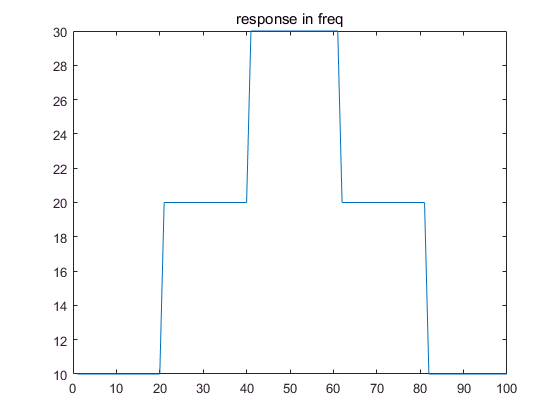

N = 100;

M = N / 2 + 1;

responseDB = ones(1, N);
index = 1;
while index <= M
    responseDB(index) = fix((index - 1)/ 20 + 1) * 10;
    index = index + 1;
end

for i = 1 : (N - M)
    responseDB(M + i) = responseDB(M - i);
end

plot(responseDB);
title('response in freq')

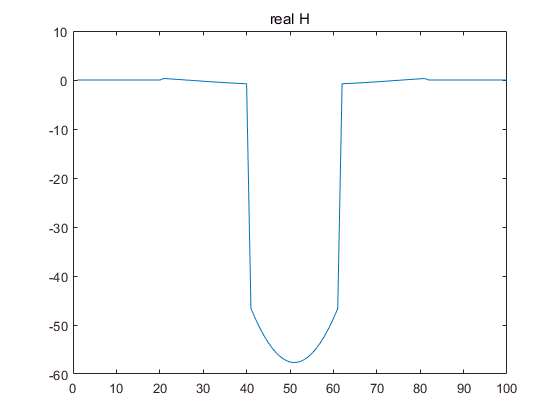


response = power(10, responseDB .* 0.05);
%response = responseDB;


w0 = 2 * pi / N;
theta = (w0 *1) .* [0 : 1 : N - 1];
phase = exp(-1i .* theta);

H = response .* phase;

plot(real(H));
title('real H');

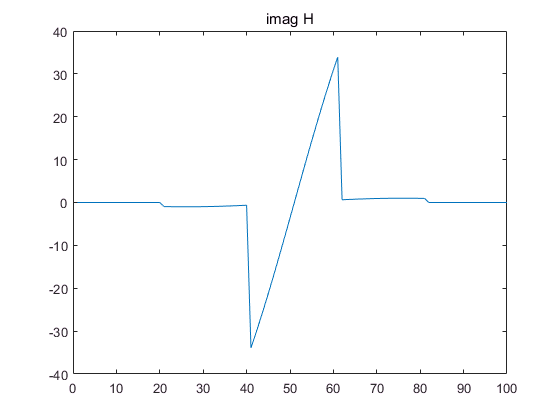


plot(imag(H));
title('imag H');


h = ifft(H)

h =  -11.3561 + 0.0000i  12.5100 - 0.0000i -11.3561 + 0.0000i   8.6395 - 0.0000i  -5.4720 + 0.0000i   2.2564 - 0.0000i   0.5766 - 0.0000i  -2.2512 + 0.0000i   2.5517 - 0.0000i  -1.9090 + 0.0000i   0.7238 - 0.0000i   0.5766 + 0.0000i  -1.4069 + 0.0000i   1.5133 + 0.0000i  -1.0648 + 0.0000i   0.2727 - 0.0000i   0.5766 + 0.0000i  -1.0785 - 0.0000i   1.0684 + 0.0000i  -0.6729 - 0.0000i   0.0487 + 0.0000i   0.5766 - 0.0000i  -0.8970 - 0.0000i   0.8114 - 0.0000i  -0.4376 + 0.0000i  -0.0905 + 0.0000i   0.5766 - 0.0000i  -0.7770 + 0.0000i   0.6370 - 0.0000i  -0.2740 + 0.0000i  -0.1896 - 0.0000i   0.5766 - 0.0000i  -0.6882 - 0.0000i   0.5053 - 0.0000i  -0.1482 + 0.0000i  -0.2670 - 0.0000i   0.5766 + 0.0000i  -0.6165 - 0.0000i   0.3977 - 0.0000i  -0.0440 + 0.0000i  -0.3320 + 0.0000i   0.5766 - 0.0000i  -0.5549 + 0.0000i   0.3039 - 0.0000i   0.0479 + 0.0000i  -0.3900 - 0.0000i   0.5766 + 0.0000i  -0.4986 - 0.0000i   0.2174 + 0.0000i   0.1335 + 0.0000i  -0.4446 + 0.0000i   0.5766 + 0.0000i  -0.444

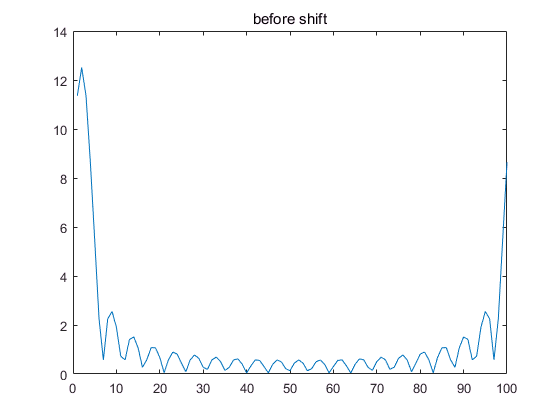


plot(abs(h))
title('before shift')


h = circshift(h',N / 2)'

h =   -0.4446 + 0.0000i   0.5766 + 0.0000i  -0.4446 - 0.0000i   0.1335 + 0.0000i   0.2174 + 0.0000i  -0.4986 - 0.0000i   0.5766 + 0.0000i  -0.3900 + 0.0000i   0.0479 + 0.0000i   0.3039 - 0.0000i  -0.5549 + 0.0000i   0.5766 - 0.0000i  -0.3320 + 0.0000i  -0.0440 - 0.0000i   0.3977 + 0.0000i  -0.6165 - 0.0000i   0.5766 + 0.0000i  -0.2670 - 0.0000i  -0.1482 + 0.0000i   0.5053 - 0.0000i  -0.6882 + 0.0000i   0.5766 - 0.0000i  -0.1896 + 0.0000i  -0.2740 + 0.0000i   0.6370 - 0.0000i  -0.7770 + 0.0000i   0.5766 - 0.0000i  -0.0905 - 0.0000i  -0.4376 + 0.0000i   0.8114 + 0.0000i  -0.8970 + 0.0000i   0.5766 + 0.0000i   0.0487 + 0.0000i  -0.6729 - 0.0000i   1.0684 - 0.0000i  -1.0785 - 0.0000i   0.5766 + 0.0000i   0.2727 - 0.0000i  -1.0648 + 0.0000i   1.5133 + 0.0000i  -1.4069 - 0.0000i   0.5766 + 0.0000i   0.7238 - 0.0000i  -1.9090 + 0.0000i   2.5517 - 0.0000i  -2.2512 + 0.0000i   0.5766 + 0.0000i   2.2564 - 0.0000i  -5.4720 + 0.0000i   8.6395 - 0.0000i -11.3561 + 0.0000i  12.5100 - 0.0000i -11.356

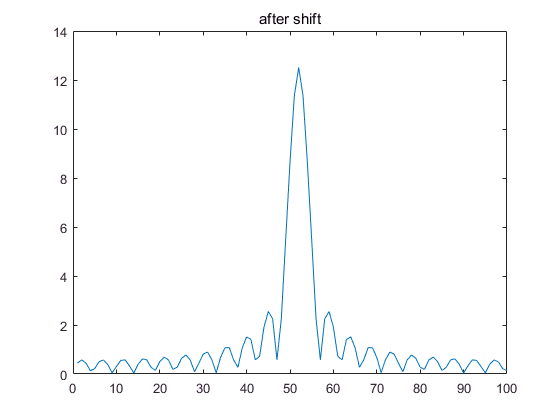




plot(abs(h));
title('after shift')

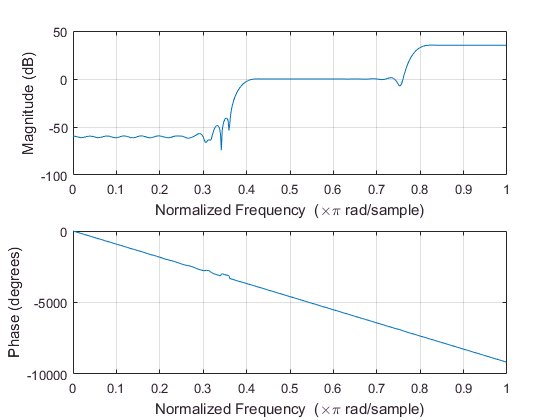

window = hanning(N);

h = h .* window';
freqz(h);